## Gabriel Werpel Fernandes

## May 2024

## Load File and Extract Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
[EEG_Oz_filtered, hdr] = processEEGData();

Data for channel A16 selected successfully


## Plot EEG Time-Series - Raw and Filtered

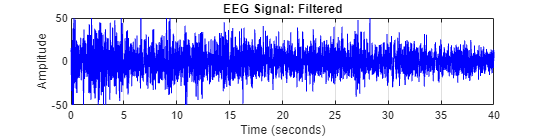

% Generate time vector
time = (1:length(EEG_Oz_filtered)) / hdr.Fs;

% Plot the filtered EEG signal
figure('Position', [0, 0, 800, 200]);
plot(time, EEG_Oz_filtered, 'b');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Filtered');
xlim([0 40]);
ylim([-50 50]);
grid on;

## Segmentation and Plot

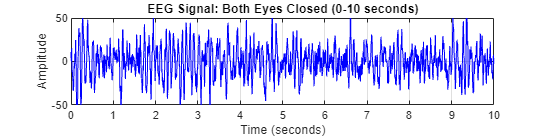

% Define the duration and sample rate
segment_duration = 10; % seconds
samples_per_segment = segment_duration * hdr.Fs;

% Segment the data
BE_Closed = EEG_Oz_filtered(1:samples_per_segment);
BE_Open = EEG_Oz_filtered(samples_per_segment+1:2*samples_per_segment);
LE_Closed = EEG_Oz_filtered(2*samples_per_segment+1:3*samples_per_segment);
RE_Closed = EEG_Oz_filtered(3*samples_per_segment+1:4*samples_per_segment);

% Define time vectors for each segment
time_segment = (0:samples_per_segment-1) / hdr.Fs;

% Plot Both Eyes Closed
figure('Position', [0, 0, 800, 200]);
plot(time_segment, BE_Closed, 'b');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Both Eyes Closed (0-10 seconds)');
xlim([0 segment_duration]);
ylim([-50 50]);
grid on;

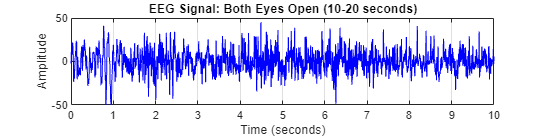


% Plot Both Eyes Open
figure('Position', [0, 0, 800, 200]);
plot(time_segment, BE_Open, 'b');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Both Eyes Open (10-20 seconds)');
xlim([0 segment_duration]);
ylim([-50 50]);
grid on;

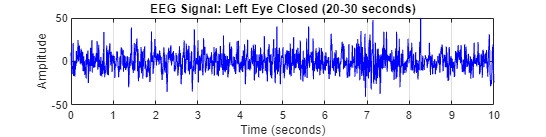


% Plot Left Eye Closed
figure('Position', [0, 0, 800, 200]);
plot(time_segment, LE_Closed, 'b');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Left Eye Closed (20-30 seconds)');
xlim([0 segment_duration]);
ylim([-50 50]);
grid on;

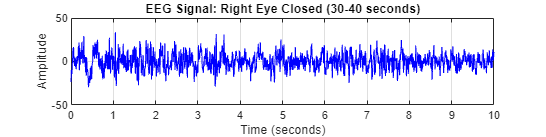


% Plot Right Eye Closed
figure('Position', [0, 0, 800, 200]);
plot(time_segment, RE_Closed, 'b');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Right Eye Closed (30-40 seconds)');
xlim([0 segment_duration]);
ylim([-50 50]);
grid on;

## Power Spectrum and Plot

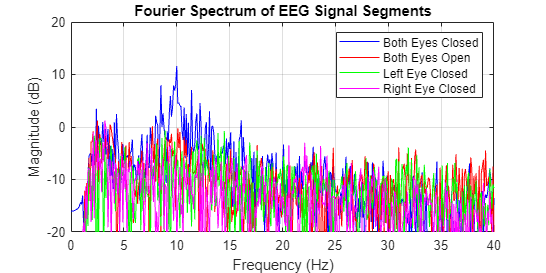

% Define axis limits
x_axis_limits = [0 40]; % Frequency axis limits (Hz)
y_axis_limits = [-20 20]; % Magnitude axis limits (dB)

% Calculate the Fourier spectrum for each segment
N = length(BE_Closed); % Length of each segment
BE_Closed_spectrum = abs(fft(BE_Closed, N)) / N;
BE_Open_spectrum = abs(fft(BE_Open, N)) / N;
LE_Closed_spectrum = abs(fft(LE_Closed, N)) / N;
RE_Closed_spectrum = abs(fft(RE_Closed, N)) / N;

% Convert magnitude to decibels (dB)
BE_Closed_spectrum_dB = 20 * log10(BE_Closed_spectrum);
BE_Open_spectrum_dB = 20 * log10(BE_Open_spectrum);
LE_Closed_spectrum_dB = 20 * log10(LE_Closed_spectrum);
RE_Closed_spectrum_dB = 20 * log10(RE_Closed_spectrum);

% Define frequency axis
freq_axis = linspace(0, hdr.Fs, N);

% Plot Fourier spectra in a single figure
figure('Position', [0, 0, 1200, 600]);

% Plot Both Eyes Closed
plot(freq_axis, BE_Closed_spectrum_dB, 'b', 'DisplayName', 'Both Eyes Closed');
hold on;

% Plot Both Eyes Open
plot(freq_axis, BE_Open_spectrum_dB, 'r', 'DisplayName', 'Both Eyes Open');

% Plot Left Eye Closed
plot(freq_axis, LE_Closed_spectrum_dB, 'g', 'DisplayName', 'Left Eye Closed');

% Plot Right Eye Closed
plot(freq_axis, RE_Closed_spectrum_dB, 'm', 'DisplayName', 'Right Eye Closed');

% Set axis labels and title
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Fourier Spectrum of EEG Signal Segments');
xlim(x_axis_limits);
ylim(y_axis_limits);
grid on;

% Add legend
legend('Location', 'northeast');
hold off;

## Power, Frequency and Reactivity

% Define frequency axis
freq_axis = linspace(0, hdr.Fs, N);

% Find indices for the frequency range 0-40 Hz
freq_range = freq_axis >= 0 & freq_axis <= 40;
freq_range_indices = find(freq_range);

% Find the maximum power and corresponding frequency within 8-12 Hz range for BE_Closed
[max_BE_Closed, idx_closed] = max(BE_Closed_spectrum_dB(freq_range_indices));
max_freq_closed = freq_axis(freq_range_indices(idx_closed));

% Use the same frequency to find power values for other segments
power_at_max_freq_open = BE_Open_spectrum_dB(freq_range_indices(idx_closed));
power_at_max_freq_le_closed = LE_Closed_spectrum_dB(freq_range_indices(idx_closed));
power_at_max_freq_re_closed = RE_Closed_spectrum_dB(freq_range_indices(idx_closed));

% Reactivity calculation (Closed - Open)
reactivity = max_BE_Closed - power_at_max_freq_open;

% Display the results
fprintf('Maximum Power in BE_Closed (8-12 Hz): %f dB at %f Hz\n', max_BE_Closed, max_freq_closed);

Maximum Power in BE_Closed (8-12 Hz): 11.623784 dB at 10.000488 Hz


fprintf('Power in BE_Open at %f Hz: %f dB\n', max_freq_closed, power_at_max_freq_open);

Power in BE_Open at 10.000488 Hz: -5.624601 dB


fprintf('Power in LE_Closed at %f Hz: %f dB\n', max_freq_closed, power_at_max_freq_le_closed);

Power in LE_Closed at 10.000488 Hz: -7.628942 dB


fprintf('Power in RE_Closed at %f Hz: %f dB\n', max_freq_closed, power_at_max_freq_re_closed);

Power in RE_Closed at 10.000488 Hz: -23.819438 dB


fprintf('Reactivity (Closed - Open): %f dB\n', reactivity);

Reactivity (Closed - Open): 17.248386 dB


## Bandwidth

% Constants for dB calculation
dB_drop = 3;

% Calculate the power in dB for the Closed condition within the alpha range
power_BE_Closed_dB = BE_Closed_spectrum_dB(freq_range_indices);

% Get the dB value 3 dB below the maximum power for the Closed condition
target_dB_closed = max_BE_Closed - dB_drop;

% Find the frequencies at -3dB points for Both Eyes Closed
left_idx_closed = find(power_BE_Closed_dB(1:idx_closed) <= target_dB_closed, 1, 'last');
right_idx_closed = find(power_BE_Closed_dB(idx_closed:end) <= target_dB_closed, 1, 'first') + idx_closed - 1;

left_freq_closed = freq_axis(freq_range_indices(left_idx_closed));
right_freq_closed = freq_axis(freq_range_indices(right_idx_closed));

% Calculate bandwidth for the Closed condition
bandwidth_closed = right_freq_closed - left_freq_closed;
fprintf('Bandwidth for BE_Closed around %f Hz: %f Hz (%f Hz to %f Hz)\n', max_freq_closed, bandwidth_closed, left_freq_closed, right_freq_closed);

Bandwidth for BE_Closed around 10.000488 Hz: 0.200010 Hz (9.900483 Hz to 10.100493 Hz)


## Coherence

## Load All Files Amblyopia data

%Process EEG Data
[newEEG_Oz_filtered, newhdr] = processEEGData();

Data for channel A16 selected successfully


## Segmentation and Plot

% Define the duration and sample rate
segment_duration = 10; % seconds
samples_per_segment = segment_duration * newhdr.Fs;

% Segment the data
newBE_Closed = newEEG_Oz_filtered(1:samples_per_segment);
newBE_Open = newEEG_Oz_filtered(samples_per_segment+1:2*samples_per_segment);
newLE_Closed = newEEG_Oz_filtered(2*samples_per_segment+1:3*samples_per_segment);
newRE_Closed = newEEG_Oz_filtered(3*samples_per_segment+1:4*samples_per_segment);

- A coherence value close to 1 indicates a high degree of similarity between the two signals at that frequency, while a value close to 0 indicates low similarity.

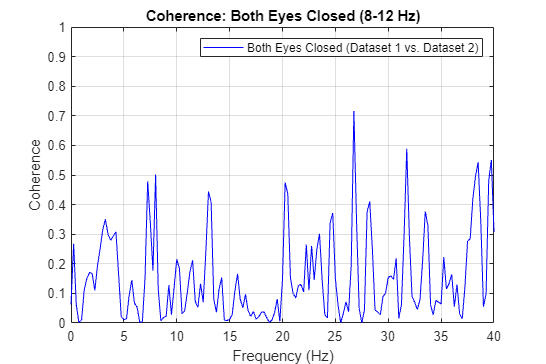

% Define axis limits
x_axis_limits = [0 40]; % Frequency axis limits (Hz)
y_axis_limits = [0 1]; % Coherence axis limits

% Compute coherence between Both Eyes Closed segments from both datasets
Fs = newhdr.Fs; % Sampling frequency
[coherence_BothClosed, freq_coherence] = mscohere(BE_Closed, newBE_Closed, [], [], [], Fs);

% Find indices for the frequency range 0-40 Hz
freq_range_coherence = freq_coherence >= 0 & freq_coherence <= 40;

% Plot coherence for Both Eyes Closed from both datasets
figure('Position', [0, 0, 1200, 800]);

plot(freq_coherence(freq_range_coherence), coherence_BothClosed(freq_range_coherence), 'b', 'DisplayName', 'Both Eyes Closed (Dataset 1 vs. Dataset 2)');
hold on;

% Set axis labels and title
xlabel('Frequency (Hz)');
ylabel('Coherence');
title('Coherence: Both Eyes Closed (8-12 Hz)');
xlim(x_axis_limits);
ylim(y_axis_limits);
grid on;

% Add legend
legend('Location', 'northeast');
hold off;